# Calcolo Numerico con Laboratorio 

# Compito a casa 

# 22 novembre 2021

## Esercizio 1

Per $\alpha=n+1/3$con $n=0,\dots,4$ si calcoli l'integrale$\displaystyle\int_0^3|x^2-5|^\alpha dx$usando le formule di integrazione numerica implementate nella function `quadratura`.

Per ciascuna formula individuare il valore di $n$ per il quale la formula di integrazione numerica converge con l'ordine previsto dalla teoria.

Per calcolare l'errore usare come valore esatto quello fornito da Matlab usando la function `integral.`

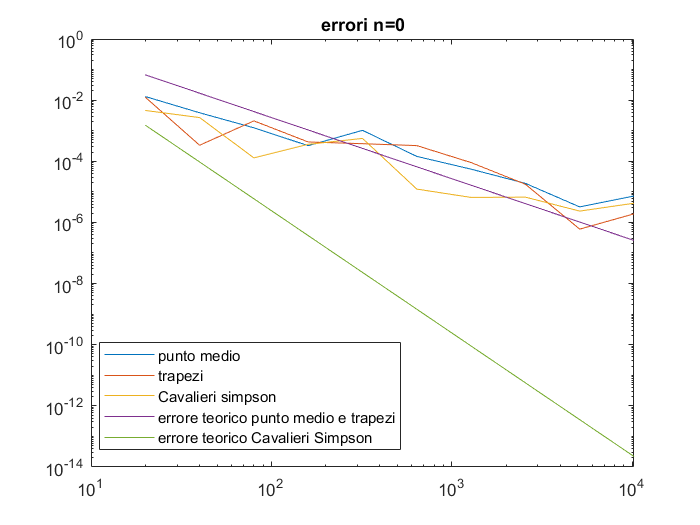

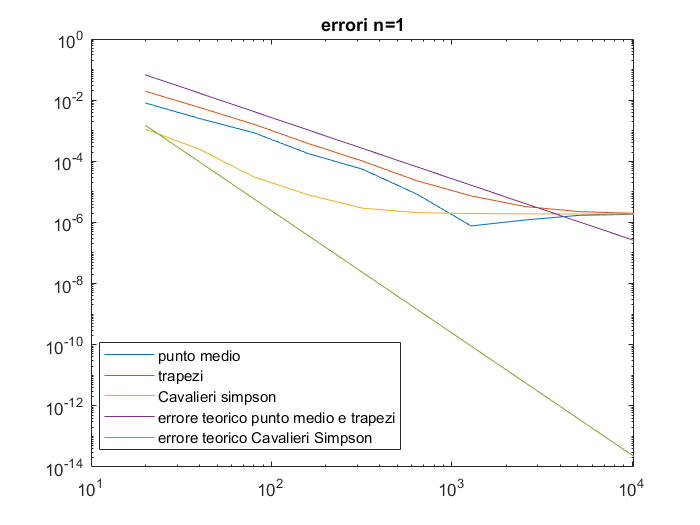

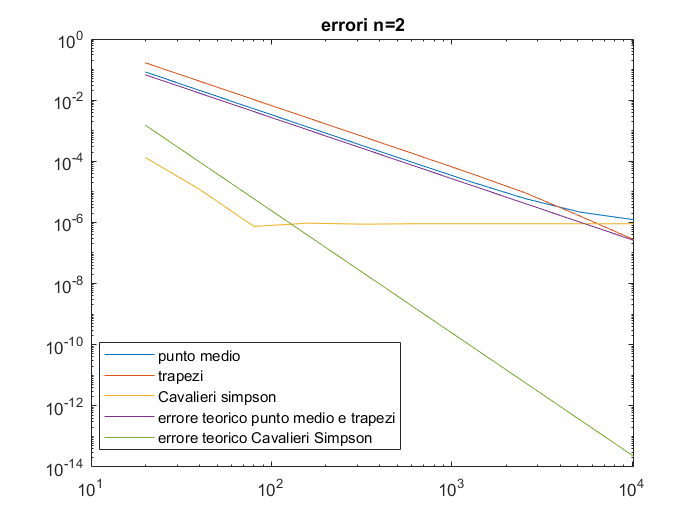

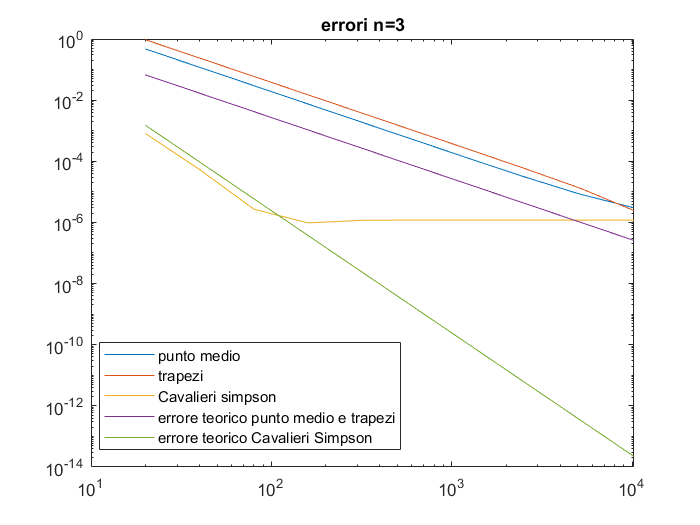

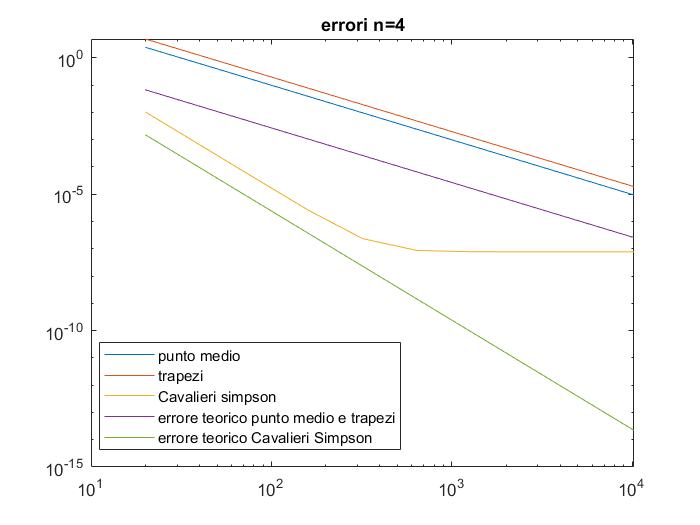

clear all
close all

a=0;b=3;
for n=0:4
    alpha=n+1/3;
    f=@(x) abs(x.^2-5).^alpha;
    Ies=integral(f,a,b);
    H=[];
    for expo=1:10
        div=10*2^expo;
        for m=1:3
            I=quadratura(f,a,b,div,m);
            E(expo,m)=abs(Ies-I);
        end
        H=[H (b-a)/div];
        V(expo)=div;
    end
    figure
    loglog(V,E(:,1))
    hold on
    loglog(V,E(:,2))
    loglog(V,E(:,3))
    loglog(V,H.^2*(b-a))
    loglog(V,H.^4*(b-a))
    title("errori n="+n)
    savefig("Es1_"+"errori n="+n)
    legend("punto medio","trapezi","Cavalieri simpson","errore teorico punto medio e trapezi","errore teorico Cavalieri Simpson",'Location','best')
end

## Esercizio 2

Calcolare i seguenti integrali:

- 
$$\int_0^\pi e^x\cos(x) dx$$


- 
$$\int_{0.1}^\infty\frac{1+\sin(x)}{x^2} dx$$


- 
$$\int_0^2 \frac{e^{-x}\cos(x)}{\sqrt{|1-x|}} dx$$


Sia $\Omega$ il dominio che si ottiene dall'intersezione fra il cerchio di centro l'origine e raggio 3 e l'insieme $\{(x,y):|x|\le 2\}$. Rappresentare graficamente la regione descritta e calcolare l'integrale doppio

 $\displaystyle\int_\Omega x^2-\frac{\sin(2y+x)}{1+x^2+y^2} dx dy$.

clear all
close all
f1=@(x) exp(x).*cos(x);
a1=0;b1=pi;
I1=integral(f1,a1,b1)

I1 = -12.0703

f2=@(x) (1+sin(x))./(x.^2);
a2=0.1;b2=inf;
I2=integral(f2,a2,b2)

I2 = 12.7262

f3=@(x) (exp(-x).*cos(x))./(sqrt(abs(1-x)));
a3=0;b3=2;
I3=integral(f3,a3,b3)

I3 = 1.0269

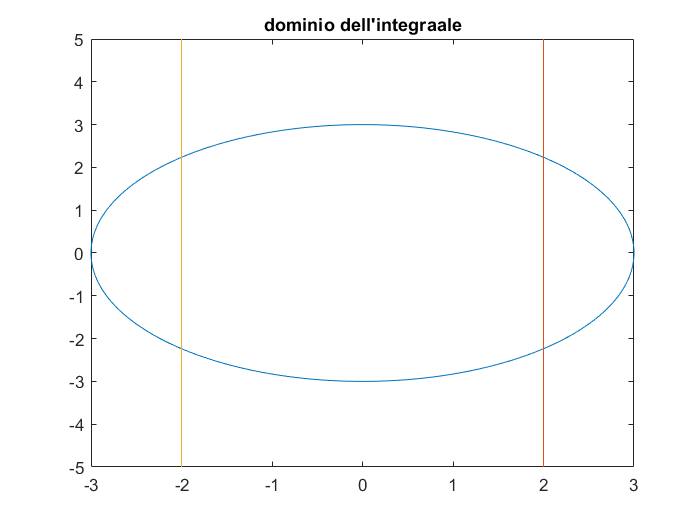


f4=@(x,y) x.^2-(sin(2*y+x))./(1+x.^2+y.^2);
circle=@(x,y) x.^2+y.^2-9;
r1=@(x,y) x-2;
r2=@(x,y) x+2;
fimplicit(circle)
hold on
fimplicit(r1)
fimplicit(r2)
title("dominio dell'integraale")
savefig("Es2_dominio")

ymax=@(x) sqrt(9-x.^2);
ymin=@(x) -sqrt(9-x.^2);
integral2(f4,-2,2,ymin,ymax)

ans = 27.3179

## Esercizio 3

Si consideri il problema di Cauchy

$y'(t)=t-5y$ per  $0\le t\le20$,    $y(0)=0.75$.

Per `N=[10,20,40,80,160]`, eseguire le seguenti istruzioni:

- calcolare la soluzione con il metodo di Eulero esplicito;

- calcolare la soluzione del seguente schema perturbato $z_{n+1}=z_n+h(f(t_n,z_n)+\rho\sin(t_n)),\quad z_0=y(0)+\rho.$ Si oserva che lo schema numerico perturbato, rappresenta la soluzione numerica del problema perturbato $z'(t)=f(t,z)+\rho\sin(t)$;

- riportare le due soluzioni in uno stesso grafico;

- calcolare l'errore assoluto al variare di $t$ e plottarlo in un grafico separato;

- appurato che il valore limite per $h$ è $0.4$, calcolare la soluzione per `N=49` ed `N=51` e riportare gli errori in valore assoluto sullo stesso grafico.

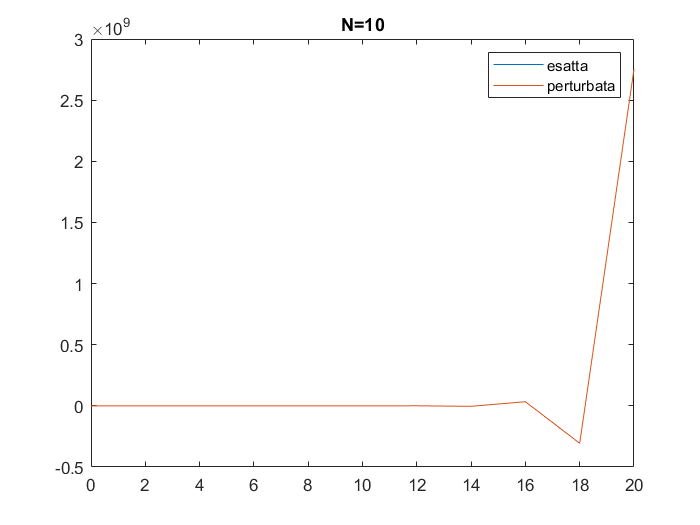

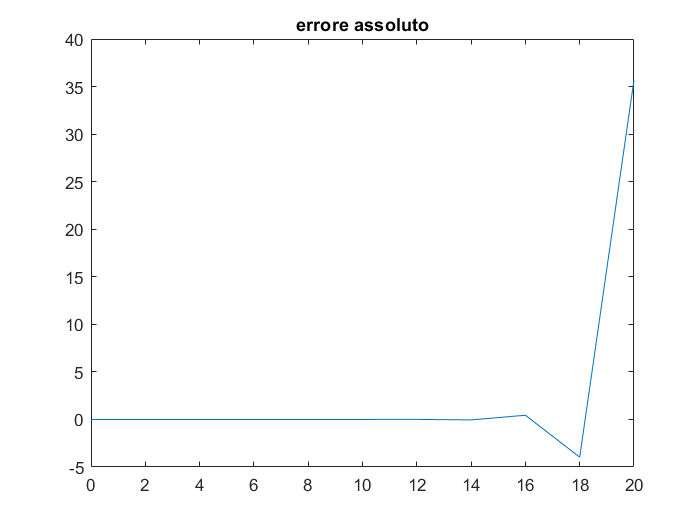

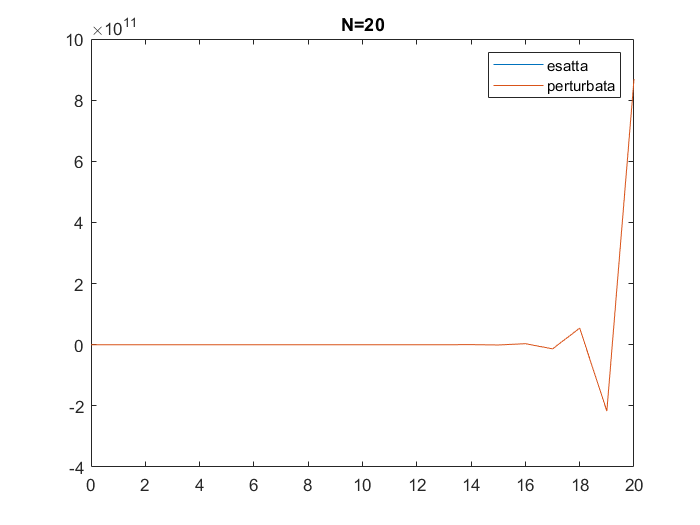

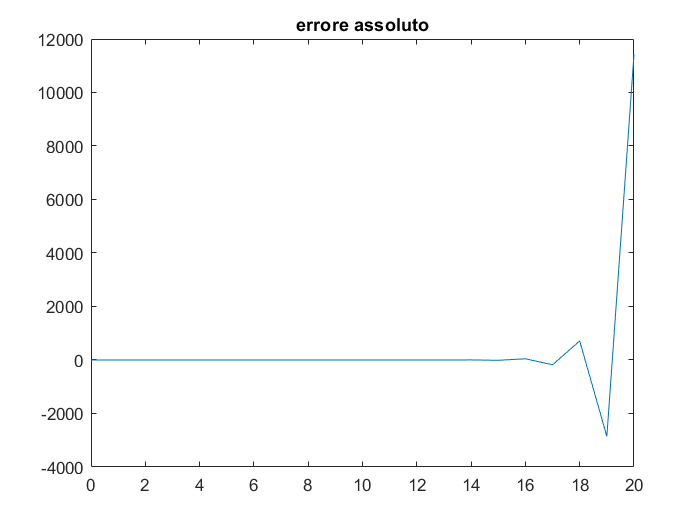

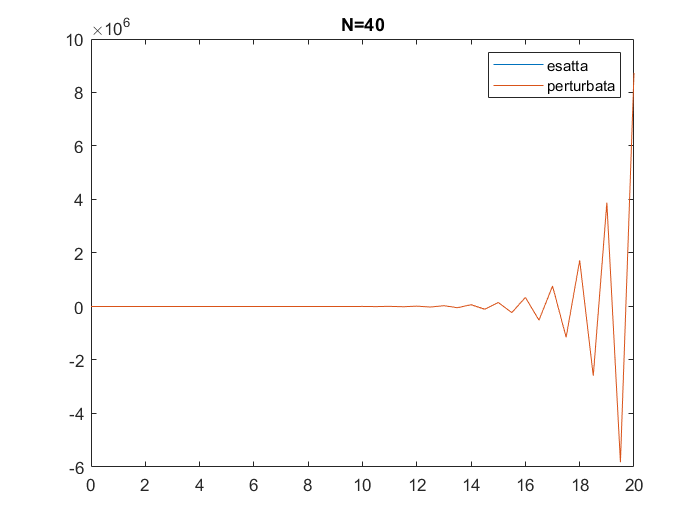

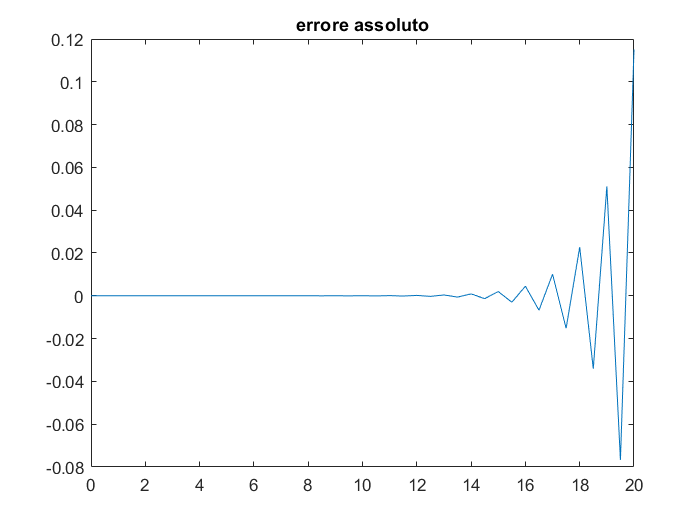

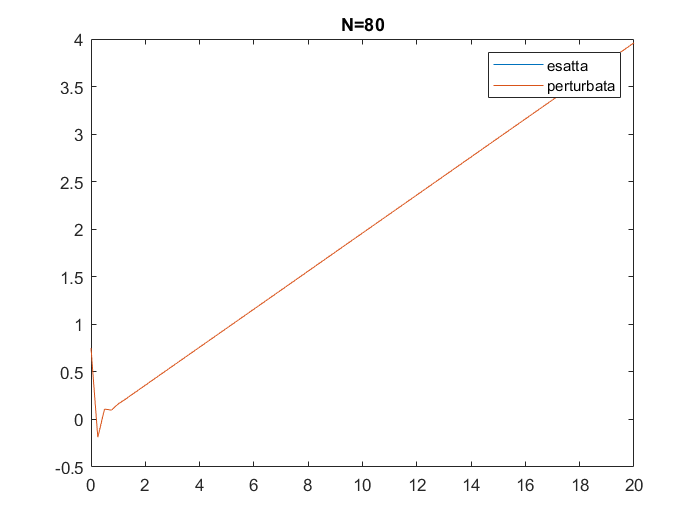

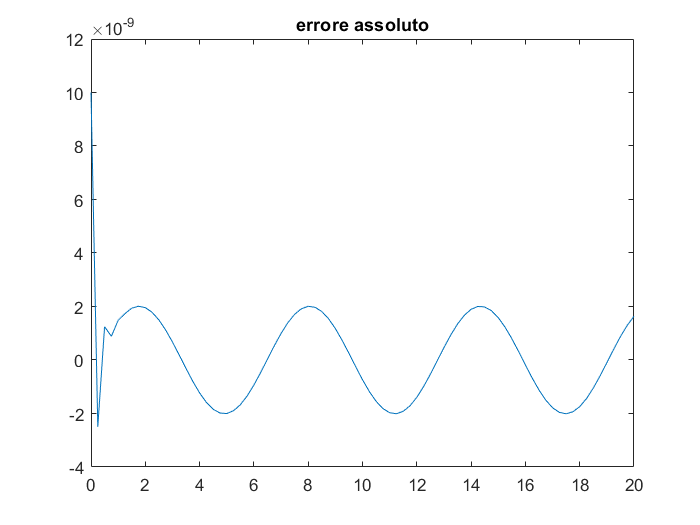

clear all
close all
N=[10,20,40,80,160];
p=1e-8;
f1=@(x,y) x-5*y;
f1p=@(x,y) x-5*y+p*sin(x);
y0=0.75;
z0=y0+p;
t0=0;T=20;
H=[];
for n=N
    [tn,un,h]=euleroEspl(f1,t0,T,y0,n);
    [tnp,unp]=euleroEspl(f1p,t0,T,z0,n);
    E=unp-un;
    H=[H h];
    figure
    plot(tn,un)
    hold on
    plot(tnp,unp)
    legend("esatta","perturbata")
    title("N="+n)
    savefig("Es3_"+"N="+n)
    figure
    plot(tn,E)
    title("errore assoluto")
    savefig("Es3_errore_N="+n)
end

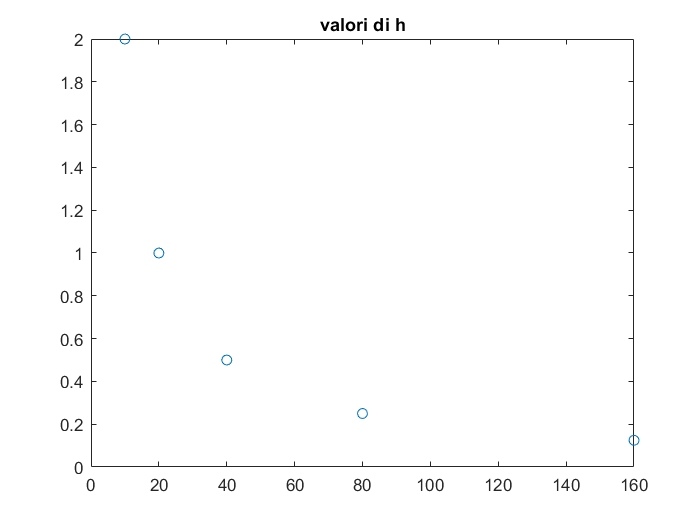

figure
plot(N,H,'o')
title("valori di h")
savefig("Es3_valori_h")

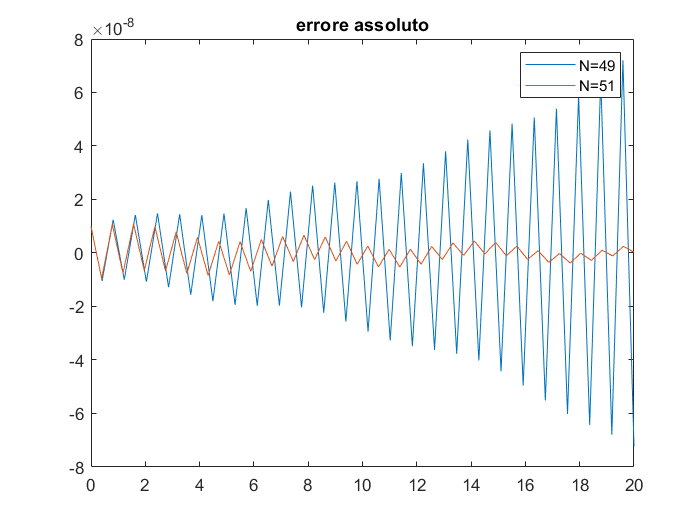

N=[49,51];
H=[];
for n=N
    [tn,un,h]=euleroEspl(f1,t0,T,y0,n);
    [tnp,unp]=euleroEspl(f1p,t0,T,z0,n);
    E=unp-un;
    H=[H h];
    plot(tn,E)
    hold on
    title("errore assoluto")
end
legend("N=49","N=51")
savefig("Es3_errore_confronto")